# Newton's Method

Newton's Method provides a simple way of solving a non-linear algebraic equation by using the value of the function and its first derivative alone. 

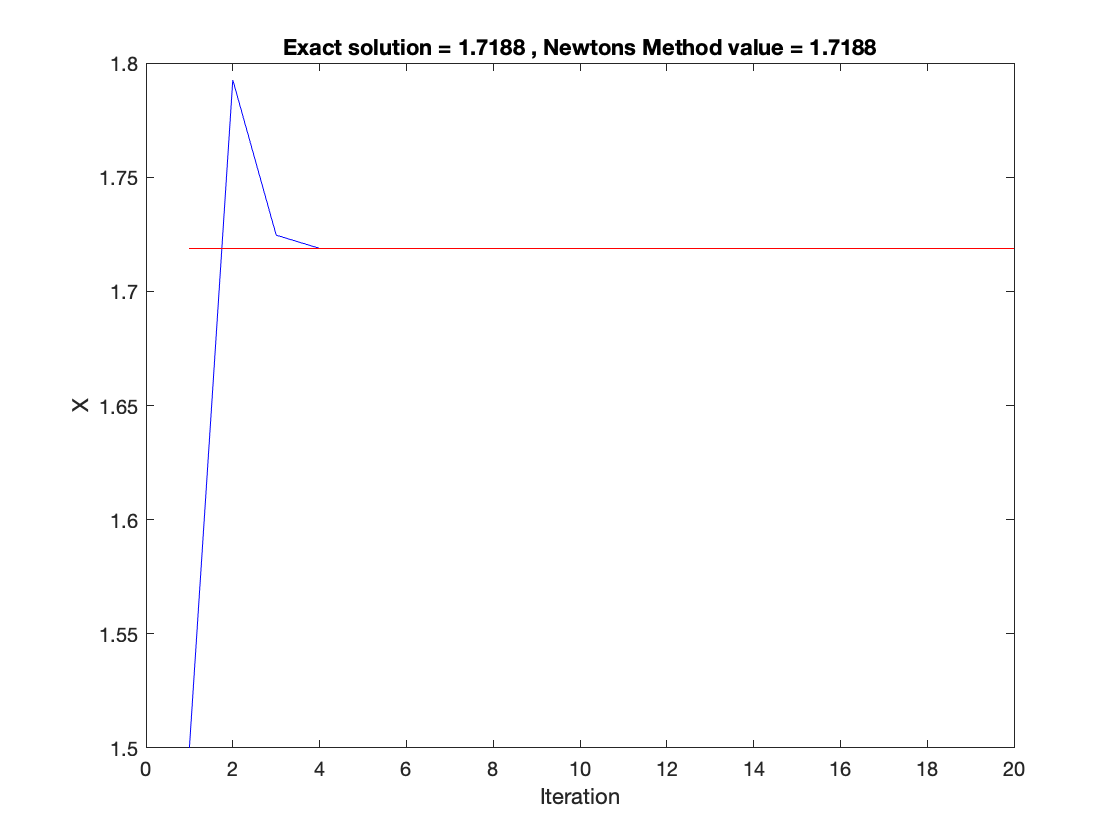

% First we have to define the function and its derivative
func       = @(x) x^5 - 15;
func_deriv = @(x) 5.0*x^4; 

% Here we define the exact solution (if we know it!) so that we compare the
% solution found by Newton's Method with the exact solution
x_solution = 15.0^(1.0/5.0);

% Next we give the program an intitial starting guess for the solution and
% the number of iterations that we would like the program to perform. 
x_init = 1.5;
n_iter = 20;

% The next lines are housekeeping to set up a vector for the value of
% the solution found at each iteration, and we put our initial guess in the
% first element of the vector
x    = zeros(n_iter,1);
x(1) = x_init;

% Now we perform the iterations using a loop, we calculate the next
% approximation to the solution using the previously found value of x.
for i_iter = 2 : n_iter
    x(i_iter) = x(i_iter-1) - func(x(i_iter-1))/func_deriv(x(i_iter-1));
end

% Lastly, we plot out the solution value at each iteration to see how
% rapidly the solution is found
figure(1)
plot((1:n_iter)', x, 'b', (1:n_iter)', x_solution*ones(n_iter,1), 'r')
title(['Exact solution = ' num2str(x_solution) ' , Newtons Method value = ' ...
    num2str(x(end))])
xlabel('Iteration')
ylabel('X')

As we can see, for this simple example, a good approximation to the solution is found very rapidly. Let's look at what happens with a different equation and in particular how our choice of intial guess changes the solution. To do this, we will change our code a little by writing a function (NewtonMMES) to contain the Newton's Method.

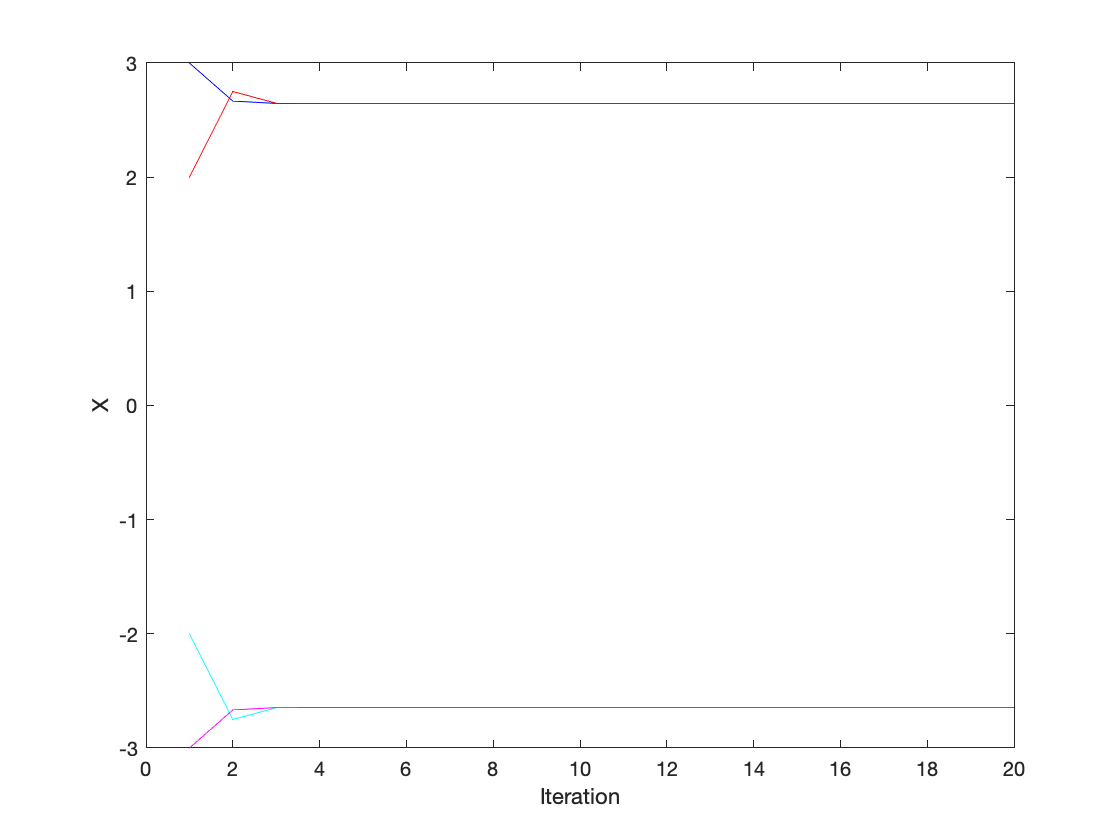

% First we have to define the function and its derivative
func       = @(x) x^2 - 7;
func_deriv = @(x) 2.0*x;

% Set the number of iterations that the code will use
n_iter = 20;

% Now use Newton's Method with different starting points
x1 = NewtonMMEES(func, func_deriv, 3.0, n_iter);
x2 = NewtonMMEES(func, func_deriv, 2.0, n_iter);
x3 = NewtonMMEES(func, func_deriv, -2.0, n_iter);
x4 = NewtonMMEES(func, func_deriv, -3.0, n_iter);

% Lastly, we plot out the solution value at each iteration to see how
% rapidly the solution is found
figure(2)
plot((1:n_iter)', x1, 'b', (1:n_iter)', x2, 'r', (1:n_iter)', x3, 'c', (1:n_iter)', x4, 'm')
xlabel('Iteration')
ylabel('X')

We know that the solution to the equation is $x = \pm\sqrt{7}  \approx \pm2.6548$, and what we find is that the code finds one or other of these solutions depending on the initial guess that we give it. 

***Excercise: ****plot out the function and detemine geometrically why Newton's Method ends up with the different solutions starting with the different initial conditions*. 

Let's now look at a different example, where we know that the root is complex. 

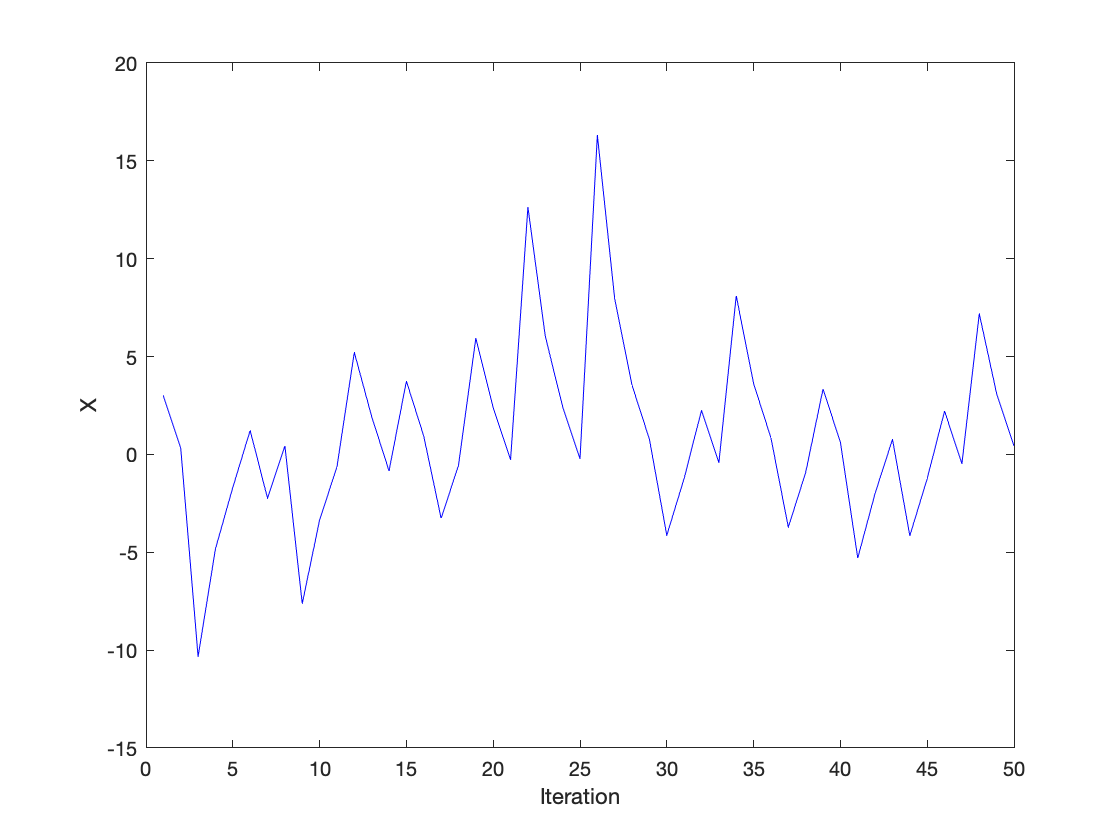

% First we have to define the function and its derivative
func       = @(x) x^2 + 7;
func_deriv = @(x) 2.0*x;

% Set the number of iterations that the code will use
n_iter = 50;

% Now use Newton's Method with different starting points
x = NewtonMMEES(func, func_deriv, 3.0, n_iter);

% Lastly, we plot out the solution value at each iteration to see how
% rapidly the solution is found
figure(3)
plot((1:n_iter)', x, 'b')
xlabel('Iteration')
ylabel('X')

Here we see something rather strange indeed. Instead of converging to a nice solution as in the previous examples, the solution bounces around almost randomly. In fact, if we extended the number of iterations to something like 500, we would find that there were very large excursions in the answer being returned. 

***Exercise: ****Sketch out the function used in the above example and determine geometrically why Newton's Method is not finding a solution. *

This last example has provided something of a problem. We don't know a priori if our computer code has actually found a solution if we only specifiy a fixed number of iterations. We can get around this by allowing the code itself to determine whether or not it has found a solution. Notice from the first example that if a solution has been found, successive iterations just produce a number that gets gradually closer to that solution. So we can get the computer to test if it has found a solution be checking to see if the difference between succssive iterations is smaller than some value that we specify. We should still include a maximum number of iterations to perform to catch those cases where no solution is found. We've implemented these changes in the function NewtonMMEES2

As some examples of using this, we look at two of the above examples again

func1       = @(x) x^5 - 15;
func1_deriv = @(x) 5.0*x^4; 

func2       = @(x) x^2 + 7;
func2_deriv = @(x) 2.0*x;

tolerance = 1.0e-6;
max_iter = 100;

x1_init = 1.5;
x2_init = 3.0;

x1 = NewtonMMEES2(func1, func1_deriv, x1_init, max_iter, tolerance);
x_solution = x1(find(x1, 1, 'last'));   % Find the last non-zero entry in x1.
disp(['Solution is x = ' num2str(x_solution)])

Solution is x = 1.7188



x2 = NewtonMMEES2(func2, func2_deriv, x2_init, max_iter, tolerance);

No solution found within specified tolerance and within Maximum number of iterations
